# Modsim Project 2

## Question

In the winter, people are often told to turn the heat down/off when they leave the house to save energy. However, there is also an argument that leaving the heat on when you leave is more efficient.  This model will seek to explain if there are any scenarios were leaving the heat on could be more energy efficient than turning it off when leaving the house for some amount of time.  Answering this question is important because it could resolve a potential spread of misinformation. In addition, it might help homeowners make more energy conscious decisions about their heating which would benefit their wallets and the environment.

**Learning Objectives**

Olivia

- Learn how to create a good modeling question

- Understand best practices in structuring a thermodynamic model

Rowan

- Want to write my own ODE’s / understand how to generate an equation for a modeling question

## Methodology

### Stock and Flow

To compare the efficiency of turning the heater off vs. leaving it on, a stock and flow model of a house was created.  In this simplified model, the stock is the internal energy of the house. A heater adds energy to the stock while the house loses energy though conduction. When the heater is on, it adds energy at a constant rate (\frac{dU}{dt} = W_{heater}) and when it is off, no heat is added. 

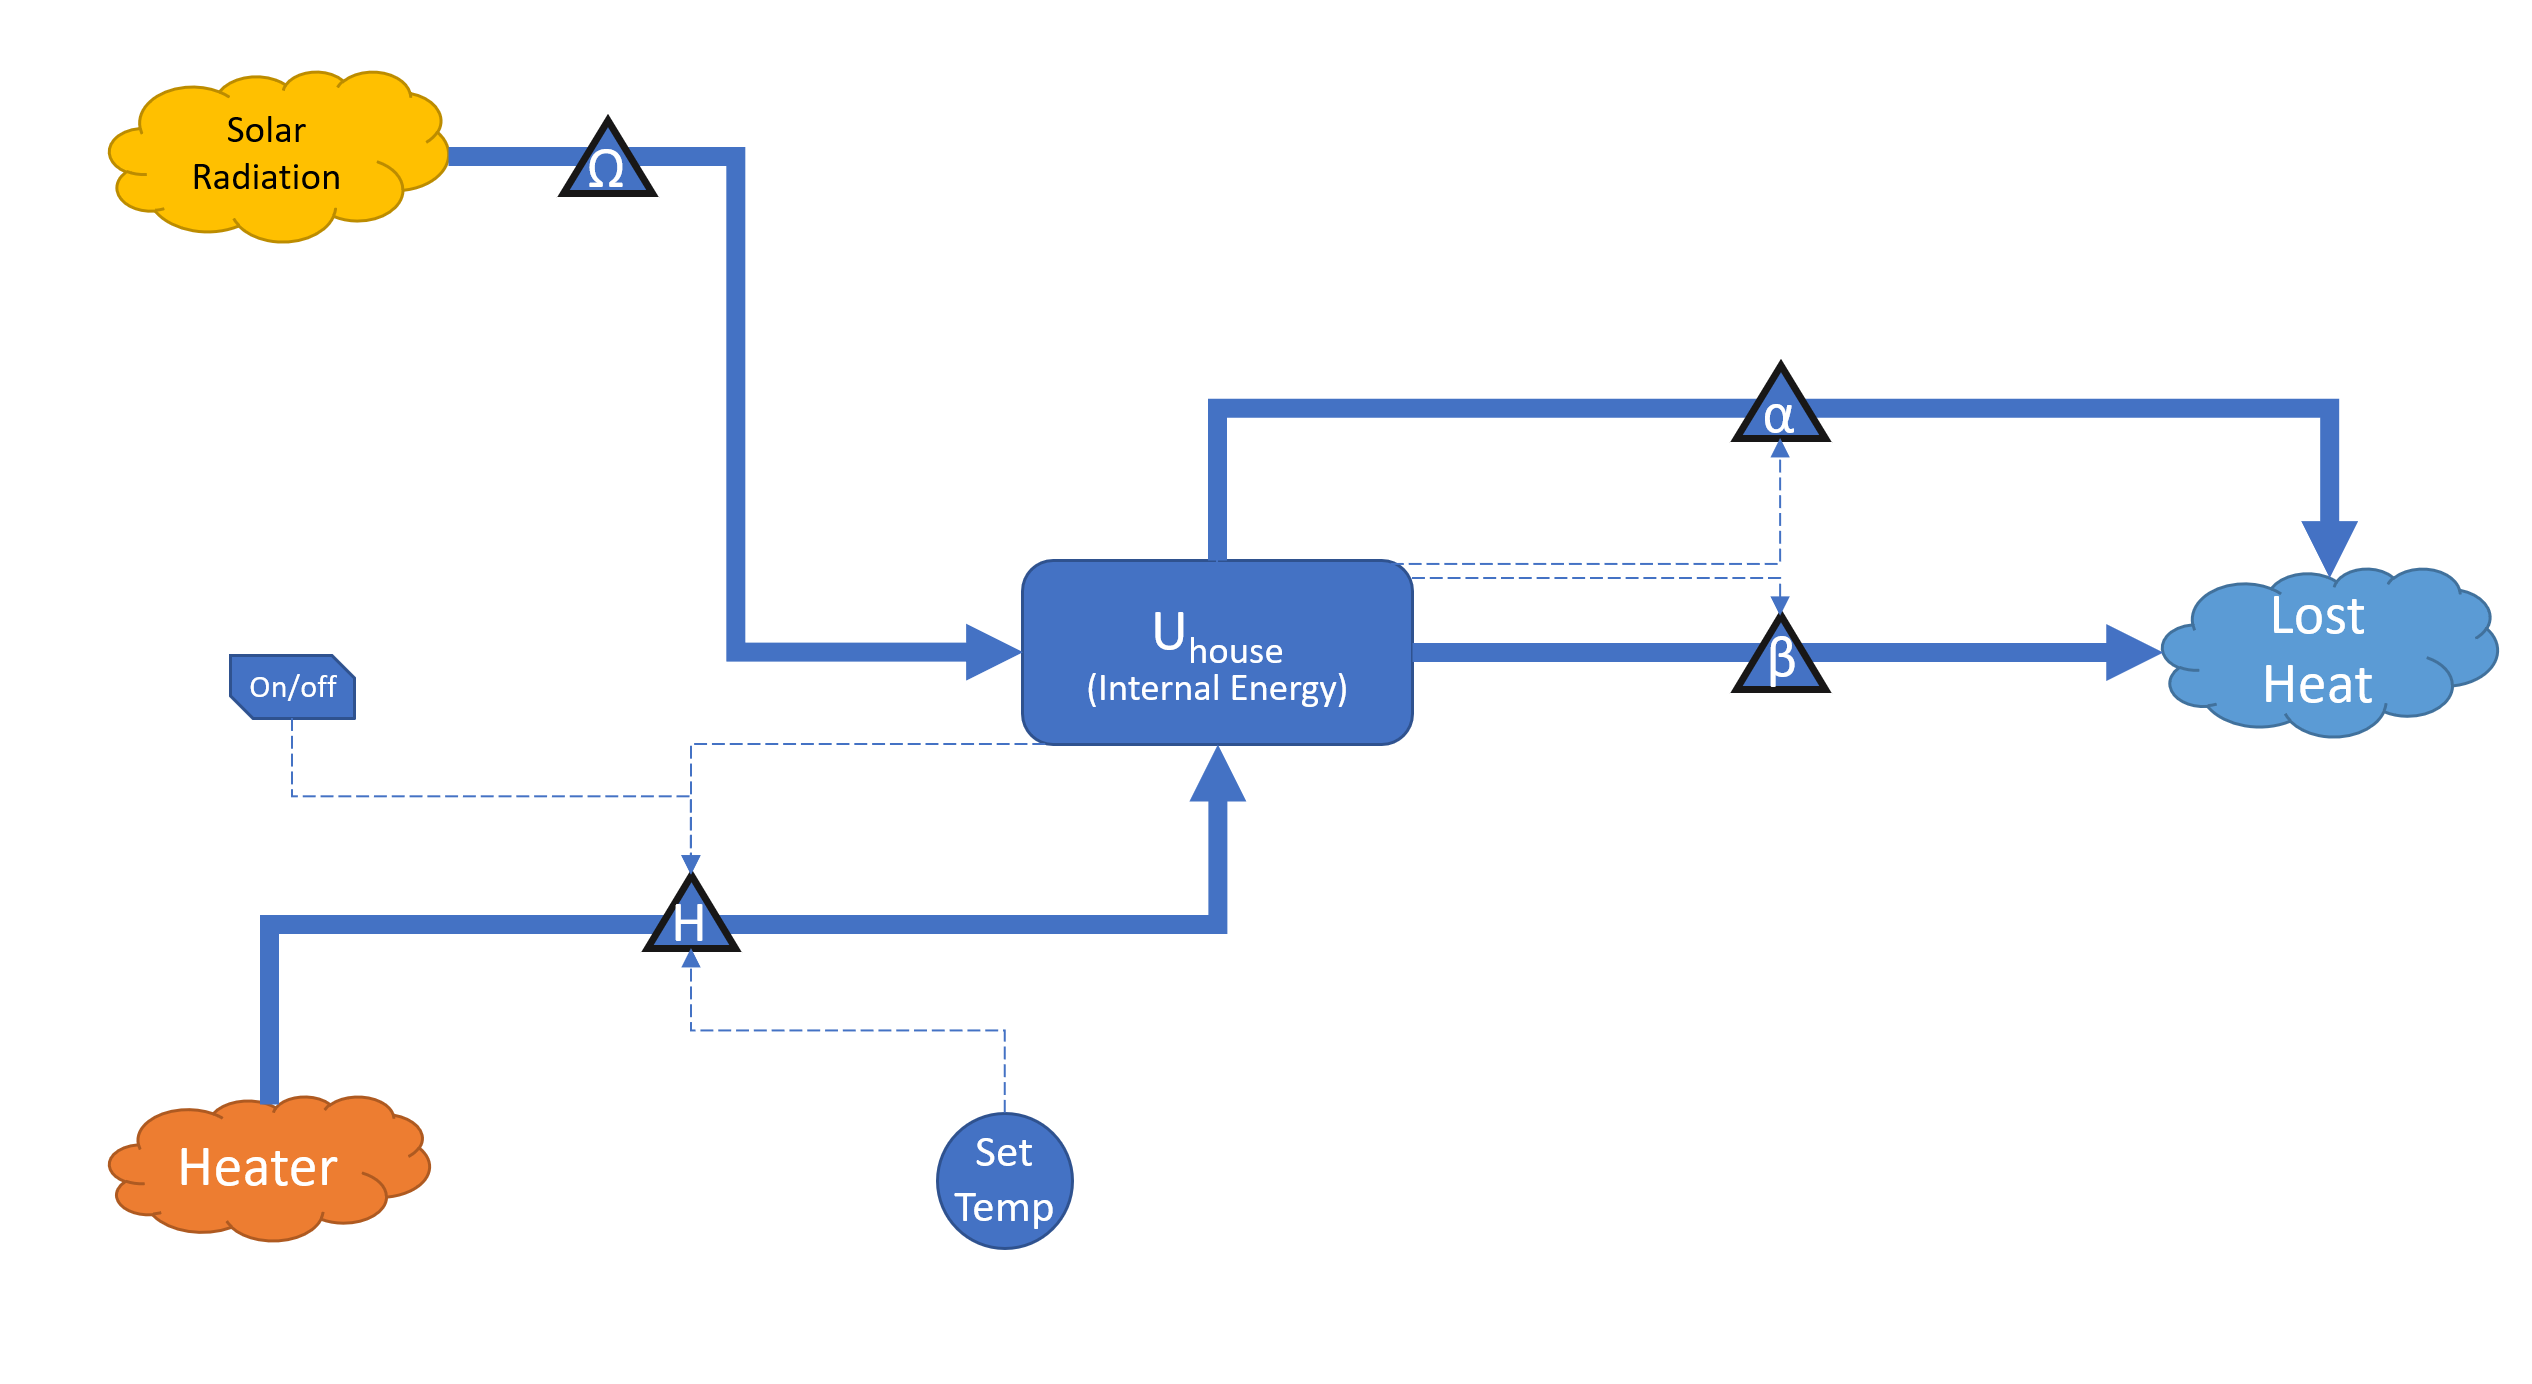

Flows in

- Solar Radiation

- Gas Furnace Heating System: this is a forced input which depends on whether the house's current temperature is below the ideal temperature.

Flows out

- Conduction through walls

- Conduction through roof

- Conduction through windows

- Conduction through doors

### Mathematical Model

From the stock and flow diagram, the following differential equation is generated.


$$\frac{dU}{dt} = H\Phi  + \Omega  - \frac{\Delta T}{R_{tot}}$$


 Where:

- $U$ is the internal energy of the house

- $H$ is the wattage of the heater

- $\Phi$ is a logical value indicating if the heater is on or off

- $\Omega$ is the energy of the sun in Watts

- $\Delta T$ is the temperature difference between the house and the environment

- $R_{tot}$ is the total conductive resistivity of the house

To calculate if the heater is on or off ($\Phi$), the model uses a discrete “overshoot and undershoot control band” which is commonly found in household thermostats. This causes the temperature of the house to oscillate around the set temperature and allows the heater to turn on less frequently.

This control system will be maintained in both scenarios while the set temperature will be varied to reflect keeping the heater on vs. turning it off. A parameter sweep can then be carried out to probe the effects of the different parameters in the model and compare the efficiencies of the two scenarios.

To calculate the total energy ($E$) used by the heater in order to assess each scenario, the model also tracks $\frac{dE}{dt} = H\Phi$

### Parameters

- ideal house temp

- wattage heater

- solar radiation possibly

- thermal mass

- wall thickness

- roof thickness

- floor thickness + material

### Assumptions

In the model, there are several assumptions that are made.  Firstly, the house being modeled is very simple and it does not contain any internal walls, furniture, appliance, etc. Therefore, the thermal mass of the house can only be a crude estimate.  However, because this generalization will affect both scenarios, the model should still make informative relative comparisons.

In addition, all the house’s internal energy is modeled by a single stock. In other words, we are assuming that the system is quasi static. This is reasonable because the rate at which the heater heats the air likely slower than the rate the air heats the solid material in the house. 

### Global Variables/Conversions

Note: for every function that needs these variables, the first line of code `global k_to_c hours_to_seconds;` must be added in the top.

global k_to_c hours_to_seconds effective_off_temp;
k_to_c = 273;
hours_to_seconds = 60*60;
effective_off_temp = -10 + k_to_c;

### **Verification and Validation**

#### **Verifying thermostat logic**

In this scenario we pretend that the house temperature oscillates on a sine curve in order to test whether the thermostat will turn on and off at our given temperature of 293 degrees K, or 20 degrees C.

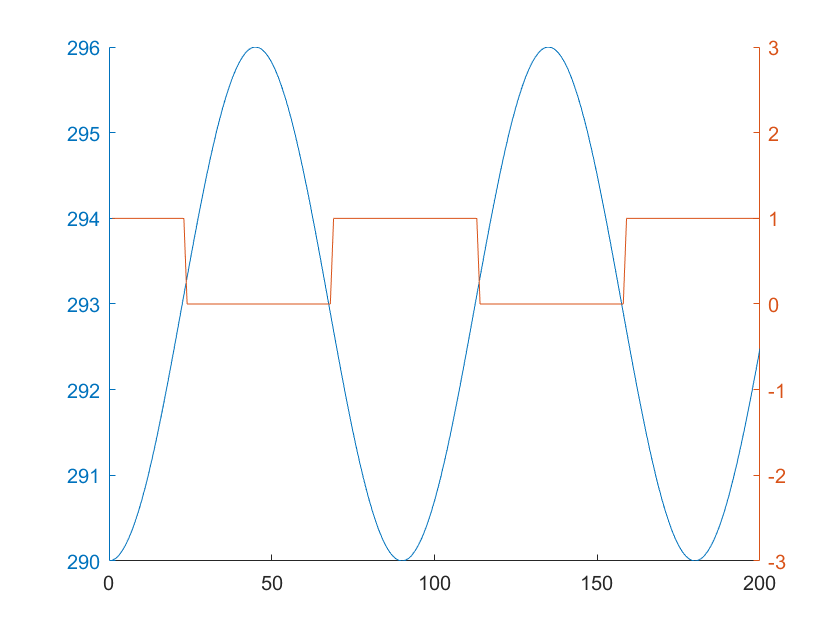

set_temp = 20 + k_to_c;
t_0 = set_temp;
heater_state = false;

%verification of thermostat logic
temp = zeros(3, 200);

for i=1:200
    temp(1,i) = i;
    t = t_0+(3*cosd(4*i+180));
    heater_state = get_heater_state(t, set_temp, heater_state);
    temp(2,i) = t;
    temp(3,i) = get_heater_state(t, set_temp, heater_state);
end

% plot
clf
hold on
yyaxis left
plot(temp(1,:), temp(2,:))
yyaxis right
plot(temp(1,:), temp(3,:))
ylim([-3 3])
hold off

#### **Verifying thermostat on at 20 deg C for six hours, then -20 deg C for six hours **

To verify the implementation of the model, a test scenario was generated where the house is initially at the ambient temperature. The house set temperature is raised to 20 C or 293 K for 6 hours, and then the set temperature is set to -20 C or 253 K for 6 hours. As -20 C is far below the ambient temperature, we can confidently assume that the house will never reach this temperature, meaning that the thermostat is effectively off.

graph_title = "Verify thermostat at 20 and -20 degree C";
% Set temp is a row matrix with the value of the desired temperature at a
% given second. Allows us to simulate the user turning down the heat and
% turning it up.
set_temp_range = [293*ones(1,6*hours_to_seconds), effective_off_temp*ones(1,6*hours_to_seconds)];
[time_range, temperature, energy_consumption, on_time, outside_temp] = house_cooling(set_temp_range, 'temp_amb');

current_house_temp defaulting to temp_amb


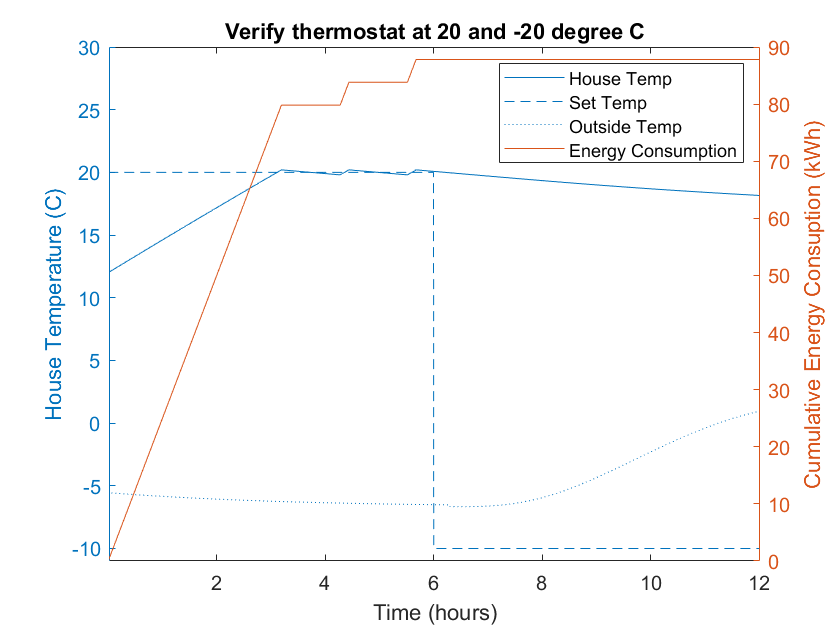

plotDefault(set_temp_range, time_range, temperature, energy_consumption, outside_temp, graph_title, [-11 30])


dispOnTime(on_time)

Total on time: 3.5122hours


## Results

#### Heater on for 12 hours at set temp 20 C

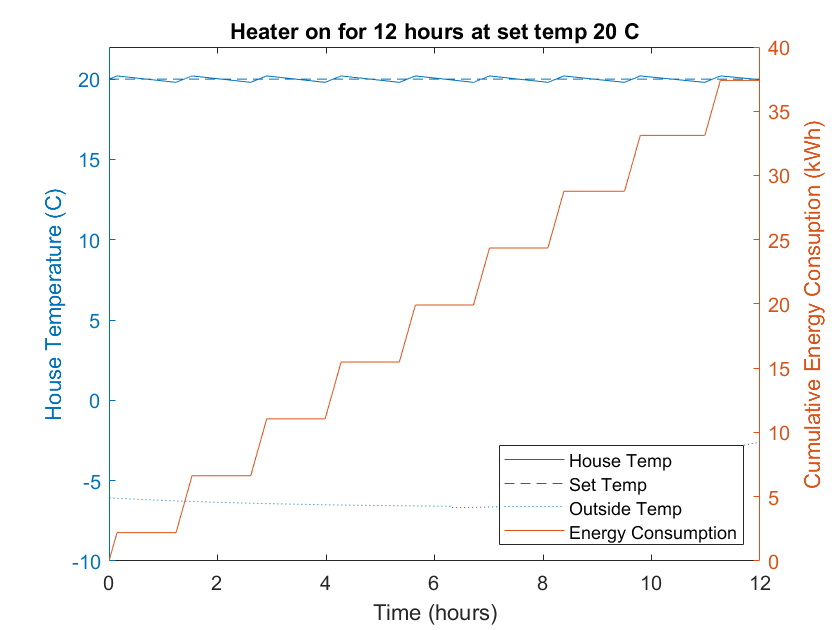

graph_title = 'Heater on for 12 hours at set temp 20 C';
set_temp = (20 + k_to_c);
set_temp_range = [set_temp*ones(1,12*hours_to_seconds)];
initial_house_temp = set_temp;

[time_range, temperature, energy_consumption, on_time, outside_temp] = house_cooling(set_temp_range, initial_house_temp);

plotDefault(set_temp_range, time_range, temperature, energy_consumption, outside_temp, graph_title, [-10 22])

dispOnTime(on_time)

Total on time: 2.4933hours


#### Heater off for 12 hours, then turn on at set temp 20 C

Initial house temperature is set temp.

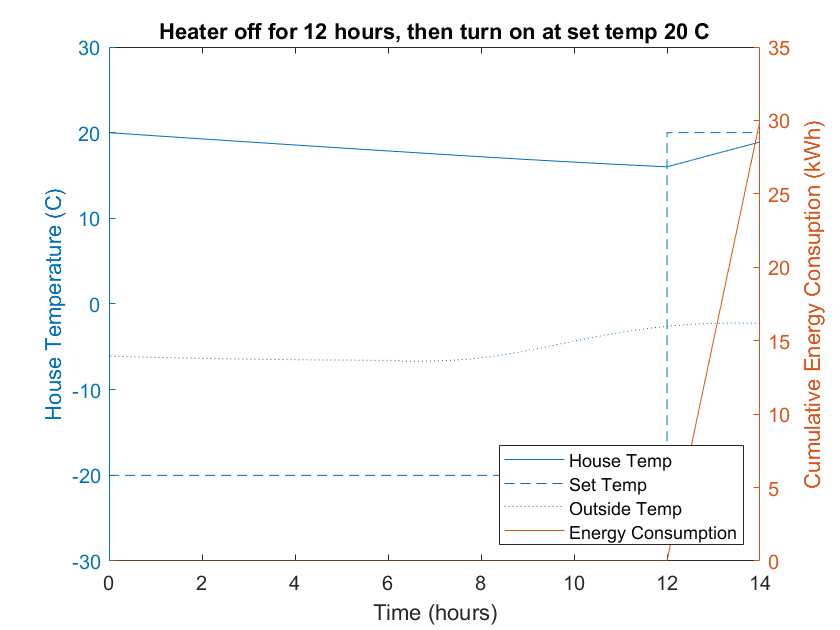

graph_title = 'Heater off for 12 hours, then turn on at set temp 20 C';
set_temp = (20 + k_to_c);
set_temp_range = [effective_off_temp*ones(1,12*hours_to_seconds), set_temp*ones(1,2*hours_to_seconds)];
initial_house_temp = set_temp;

[time_range, temperature, energy_consumption, on_time, outside_temp] = house_cooling(set_temp_range, initial_house_temp);

plotDefault(set_temp_range, time_range, temperature, energy_consumption, outside_temp, graph_title, [-30 30])

dispOnTime(on_time)

Total on time: 2hours


#### Heater at 12 degrees C for 12 hours, then up to 20 C

Initial house temperature is set temp.

Note: this is exactly the same as the previous one because we haven't taken weather changes into account (i'm assuming)

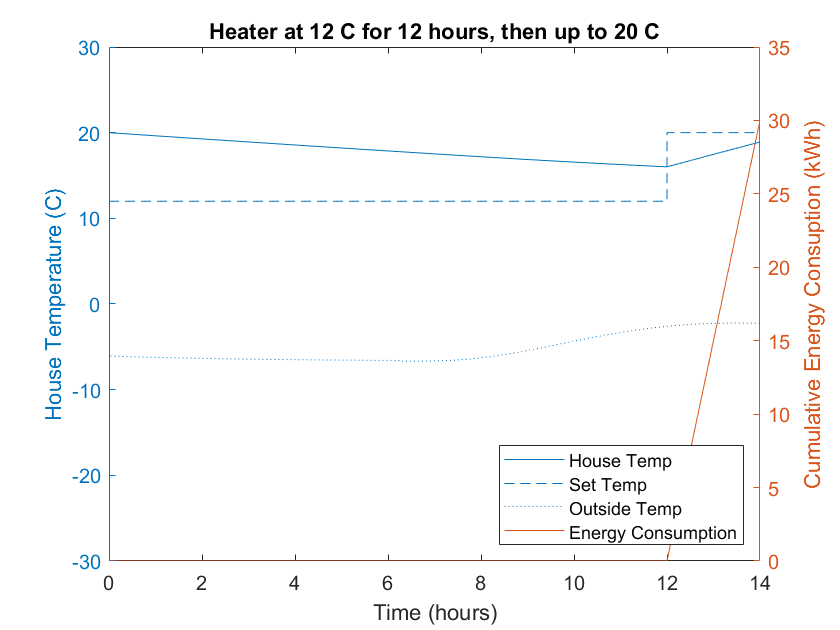

graph_title = 'Heater at 12 C for 12 hours, then up to 20 C';
set_temp_range = [(12 + k_to_c)*ones(1,12*hours_to_seconds), (20 + k_to_c)*ones(1,2*hours_to_seconds)];
initial_house_temp = (20 + k_to_c);

[time_range, temperature, energy_consumption, on_time, outside_temp] = house_cooling(set_temp_range, initial_house_temp);

plotDefault(set_temp_range, time_range, temperature, energy_consumption, outside_temp, graph_title, [-30 30])

dispOnTime(on_time)

Total on time: 2hours


## Interpretation

## Methodology

questions to consider

- what heating systems are there / how fast + energy efficient is the heating system

- house specifications

-     how big is the house

-     what kind of insulation

-     roof is flat, house is cube

- the outside world

-     ambient temperature + how it changes over the day

assumptions/things we are going to ignore

- the existence of night

- rooms - might affect the 

- in winter - ambient temperature always going to be colder

- convection is not significant enough of a energy loss that it needs to be modeled - lumping inside convection, walls conduction, outside convection

### Stocks

internal energy of the house

### Flows

### Defining our house

Our house is a cube with a flat roof

average sqft of a house in MA: 1,744 square feet = 162.022902 square meters

width = 10; % m
length = 15; % m
width*length % size of house in square meters

ans = 150

height = 3 % m, approx 10 ft

height = 3

% define thermal mass
% add windows

#### Stock and Flow


$$\frac{dU}{dt} = P_{heater} + P_{sun}  - \frac{\Delta T}{R_{tot}}$$
